# **IO3xx Quadrature - Loopback**

This example demonstrates the quadrature code module functionalities using a quadrature encoder **QAE v3** and a quadrature decoder **QAD v5*****,*** which are both on the same I/O module connected to a loopback. You can test the basic functionality of the quadrature code modules by running this loopback test. 

## Setup

### Prerequisites

You will require the following to run this example:

- Speedgoat real-time target machine with one I/O module from the IO3xx family installed

- A Speedgoat configuration file that supports at least **1 x QAD channel** and **1 x QAE channel**

- Connector cable from the I/O module to the terminal board

- Terminal board with jumper wires

### Test Setup

In this example, data is sent from the QAE to the QAD. You must therefore connect the pins on the terminal board where these channels are located. The exact pins depend on the configuration file (bitstream) used. 

In the pin mapping of your configuration file, locate the functionalities specified in the table below and then locate the corresponding pins on the terminal board. Connect theses pins with jumper wires. 

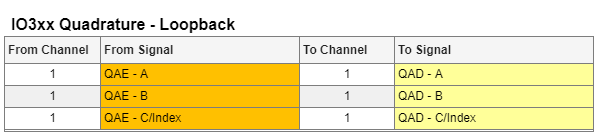

## Initialize and Open the Simulink model

 
% Open Simulink model
modelName = 'sgMdl_IO3xx_Quadrature_Loopback';
open_system(modelName);

Before the Simulink model can be built, the I/O module and configuration file must be specified in the IO3xx Setup block, as this example can be executed on different configurable I/O modules. First, open the mask of the IO3xx Setup block and select your I/O module from the drop-down. Once the mask has extended, select the configuration file that supports the required functionalities.

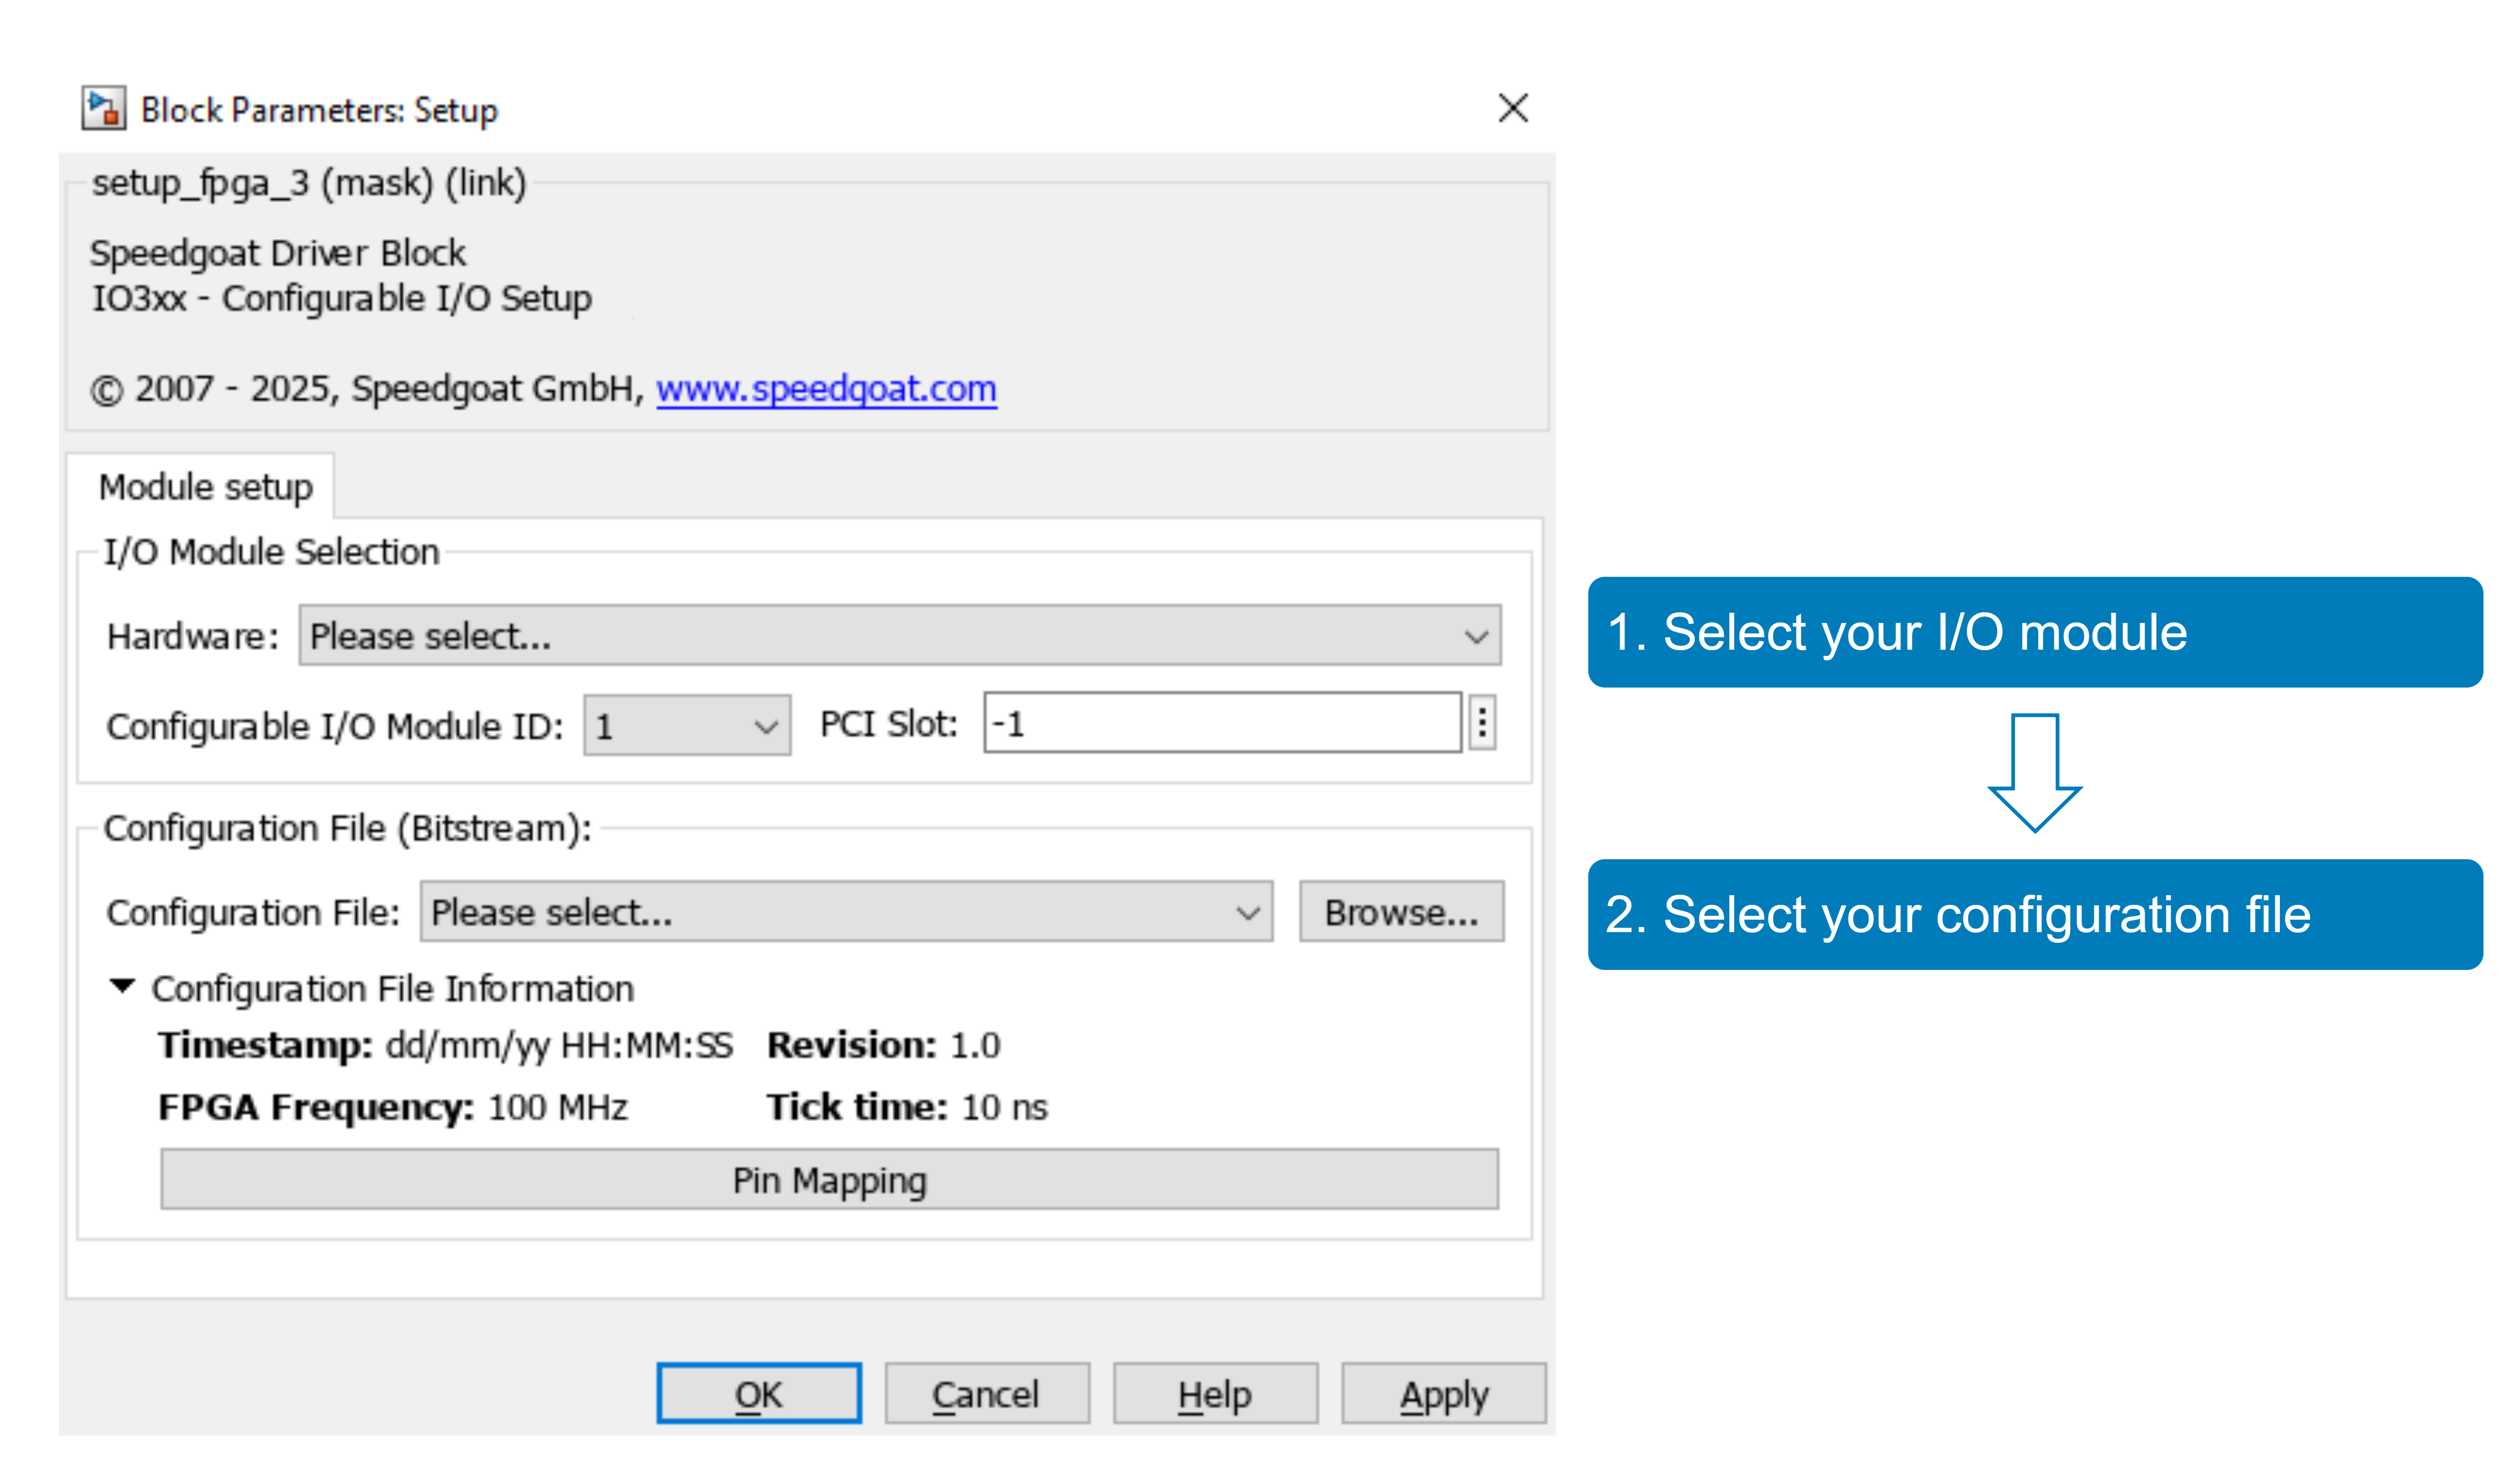

With the **Pin Mapping** button you can now check where the functionalities are located.

## Model Description

### QAE Signal generation

In the model, the QAE generates qadrature signals as depicted in the following image (Example with 8 Slots per turn):

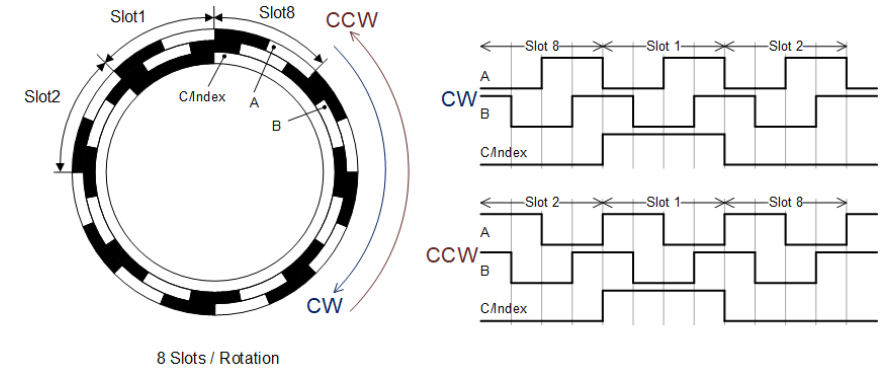

### QAD Signal analyzing

The QAD analyzes the data as depicted in the following image (Example with 4 Slots per turn):

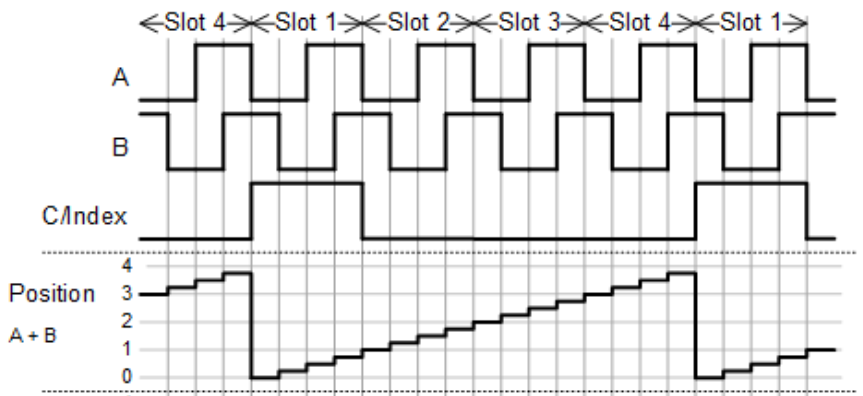

### Model Behavior

In the example model, both the [Quadrature Encoder (QAE)](https://www.speedgoat.com/help/slrt/page/io_main/refentry_quadrature_encoder_v3) and the [Quadrature Decoder (QAD)](https://www.speedgoat.com/help/slrt/page/io_main/refentry_quadrature_decoder_v5) block are set to 8 slots per turn. The QAD block is configured to use the A and the B signal to detect the position and the index (signal "C/Index" described in the above image) is used to reset the detected position to 0.

In this model, the QAE Block is fed with a constant value on the **Speed [RPM]** input. Also note that in the model the QAD block will keep it's position output on zero until 3.8s of the simulation.

## Build, Download, and Run the Example

To run the example, either run the following code section or click the **Run on Target** button in the **REAL-TIME** tab in the Simulink model:

 
% Build the Simulink model
slbuild(modelName);         % this will create the real-time application file (.mldatx)

% Create and connect to the Speedgoat real-time target machine
tg = slrealtime;            
tg.connect;

% Download and install the real-time application on the target machine
tg.load(modelName); 
tg.setStopTime(10);

% Connect the Simulink model with external mode to the real-time application on the target machine
set_param(modelName,'SimulationMode','external')    % put model into External Mode
set_param(modelName,'SimulationCommand','connect')  % connect with External Mode  

% Start the real-time application
tg.start;

% Wait a few seconds and then stop the real-time application on the target machine
pause(10)
tg.stop;

## Check the Results

To check if the loopback is working as expected, open the Simulink scope that is connected to the following signals:

- QaePosition: This is a feedback signal of the QAE signal generation itself, indicating the actual slot position.

- QadPosition: This is the measured position output of the QAD.

- QadSpeed: This is the measured speed of the QAD.

- QadTurns: This is the measured number of turns of the QAD. This signal increases in case a complete turn of the wheel with the set number of slots happened

- QadSpeedValid: This signal indicates when the QAD speed measurement signal is valid.

- QadIndexFound: This signal indicates when the signal "C/Index" was detected by the QAD for the first time.

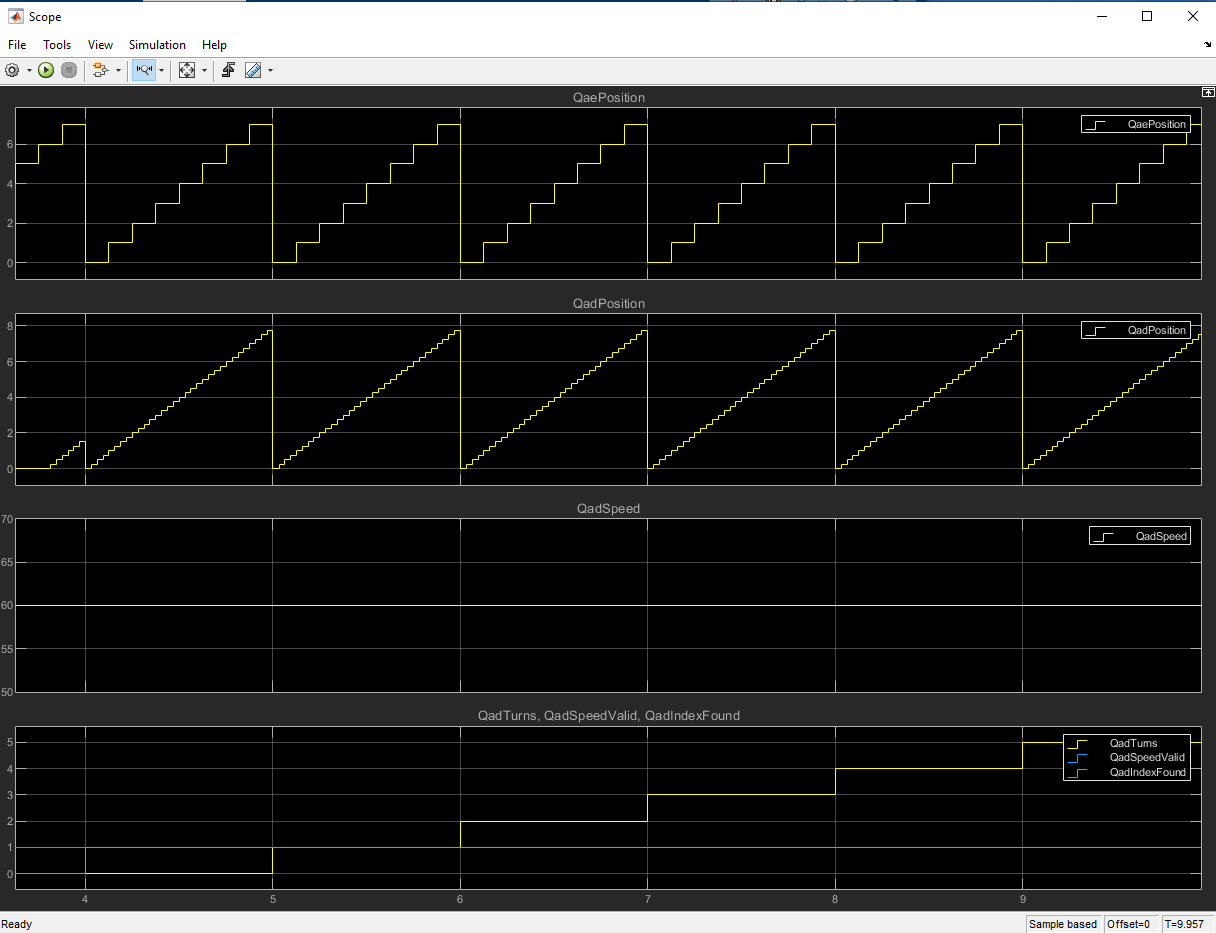

Note that the QadPosition got 4 times better resolution than the QaePosition. This is due to the fact that the QAE just indicates it's current slot number, while the QAD detects the A and the B signal that divides one slot into four portions.

The QadPosition and the QadIndexFound signal are low until about 3.8s of the simulation time. This is due to these signals are actively kept zero by keeping high the inputs **Clear Position** and **Clear Index Found Flag** of the QAD block (see the model).

## Additional References

- [Quadrature documentation (Encoder v3, Decoder v5) and examples](https://www.speedgoat.com/help/slrt/page/io_main/refentry_ref_quadrature)

[](https://www.speedgoat.com/help/slrt/page/io_main/refentry_quadrature_usage_notes)